# Create y & X Data

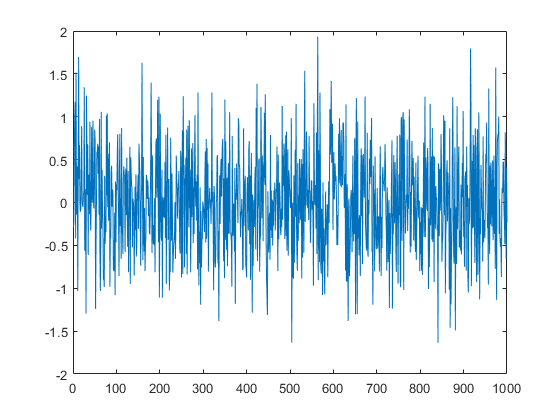

nobs = 1000;
nvar = 5;
% rng('default');
X                   = randn(nobs,nvar);
Beta                = rand(1,nvar);
Beta                = Beta/sum(Beta);
ErrorVarianceActual = 0.05;
y                   = X*Beta' + ErrorVarianceActual*randn(nobs,1);
R = array2table(X);
R.y = y;
figure;
plot(y)

disp(Beta)

    0.3451    0.0768    0.4340    0.1047    0.0394



## OLS

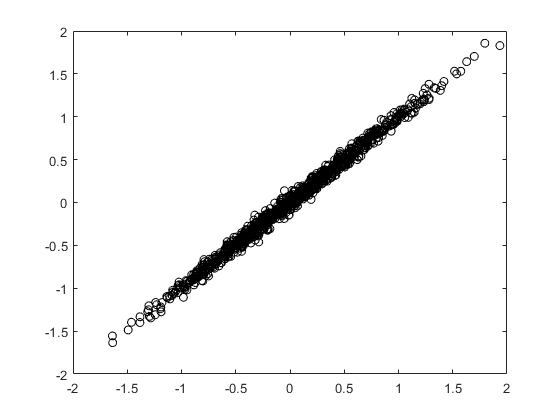

LM   = fitlm(X,y,'Intercept',false);
yEst = predict(LM,X);
ErrorVarianceEstimated = std(yEst - y);
figure
plot(y,yEst,'ko')

T = table();
T.BetaActual      = Beta(:);
T.BetaEstimatedLM = LM.Coefficients.Estimate

T = 5×2 table
    BetaActual    BetaEstimatedLM
    __________    _______________

      0.34513         0.34768    
     0.076779        0.076664    
      0.43399         0.43607    
      0.10471         0.10545    
     0.039395        0.037891    



E = table();
E.ErrorVarianceActual    = ErrorVarianceActual;
E.ErrorVarianceEstimated = ErrorVarianceEstimated;

## MVRegress - Cholesky Decomposition

[T.BetaMVR,Sigma,E,CovB,logL] = mvregress(X,y);
disp(T)

    BetaActual    BetaEstimatedLM    BetaMVR 
    __________    _______________    ________

      0.34513         0.34768         0.34768
     0.076779        0.076664        0.076664
      0.43399         0.43607         0.43607
      0.10471         0.10545         0.10545
     0.039395        0.037891        0.037891



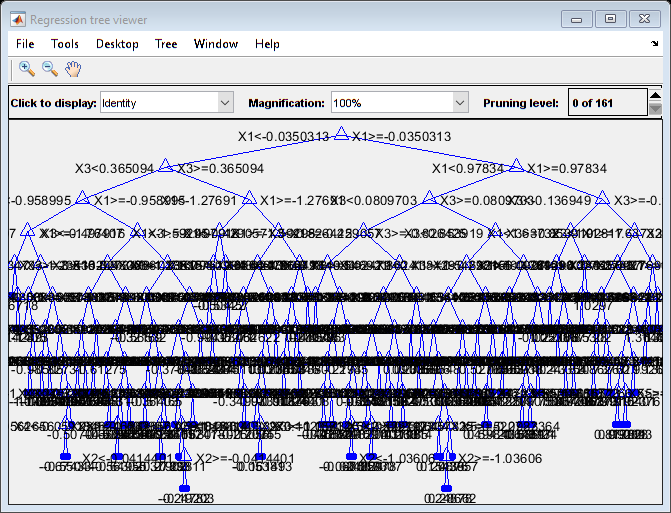

[trainedModel, validationRMSE] = trainRegressionModel(R);
view(trainedModel.RegressionTree,'mode',"graph")

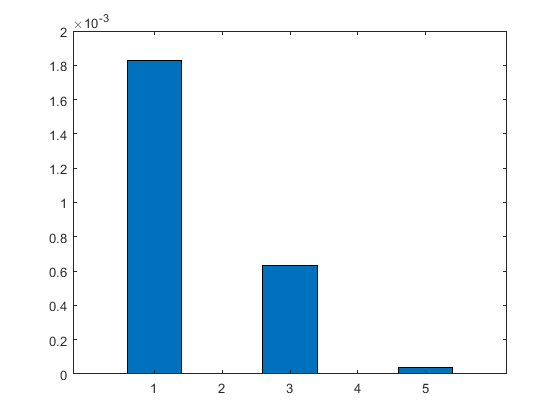

figure; bar(predictorImportance(trainedModel.RegressionTree))

## Estimate Beta from Covariance

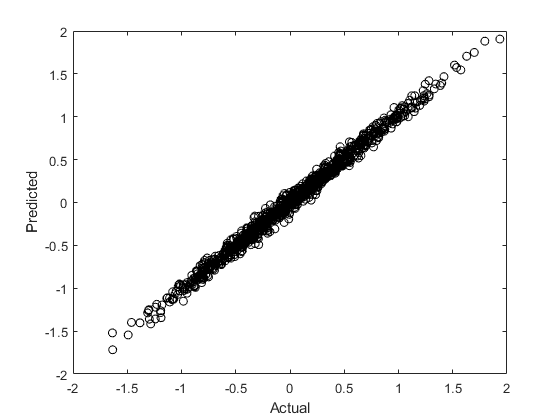

C = cov([y X]);
d = diag(C);
d = d(2:end);
T.BetaEstimatedCov = (C(1,2:end)./d')';
yEstCov = X*T.BetaEstimatedCov;
figure
plot(y,yEstCov,'ko')
xlabel('Actual')
ylabel('Predicted')

disp(T)

    BetaActual    BetaEstimatedLM    BetaMVR     BetaEstimatedCov
    __________    _______________    ________    ________________

      0.34513         0.34768         0.34768         0.35169    
     0.076779        0.076664        0.076664        0.094306    
      0.43399         0.43607         0.43607         0.45209    
      0.10471         0.10545         0.10545        0.086323    
     0.039395        0.037891        0.037891        0.039395    



## Estimate Beta from QR Decomposition

βest = inv(X'X) * X'y

X'X * β = X'Y * X'X * β = X'Y

(QR)' * (QR) * β = (QR)' * Y * (QR)' * (QR) * β=(QR)' * Y

R' * (Q'Q) * R * β = R' * Q'Y * R'(Q'Q) * Rβ = R'Q'Y

R'R * β = R'Q'Y * R'R * β= R'Q'Y

inv(R') * R'R *β = inv(R') * inv(R'Q'Y(R') * R'R * β=inv(R') * R'Q' * Y

R***β** = Q'Y

% Factor the design matrix and transform the response vector.
[Q,R,perm] = qr(X,0);
Qy = Q'*y;

% Use the rank-revealing QR to remove dependent columns of X.
[R,Qy] = removeDependentCols(Qy,R,perm,nobs,nvar);

% Compute the LS coefficients, filling in zeros in elements corresponding
% to rows of R that were thrown out.
b = zeros(nvar,1);
b(perm,1) = R \ Qy;

T.BetaEstimatedQR = b

T = 5×5 table
    BetaActual    BetaEstimatedLM    BetaMVR     BetaEstimatedCov    BetaEstimatedQR
    __________    _______________    ________    ________________    _______________

      0.34513         0.34768         0.34768         0.35169            0.34768    
     0.076779        0.076664        0.076664        0.094306           0.076664    
      0.43399         0.43607         0.43607         0.45209            0.43607    
      0.10471         0.10545         0.10545        0.086323            0.10545    
     0.039395        0.037891        0.037891        0.039395           0.037891    
